**SISO Uncertainty Modeling**

Example 1

Consider an uncertain mass-spring-damper model with mass on the range (1,3) kg, the stiffness with a nominal value of 100 and 20% uncertainty, and the damping coefficient 10 plus/minus 5.  Here we'll use the *ureal* command to build the model for us.

s = tf('s');
m = ureal('m',2,'Range',[1,3]); 
k = ureal('k',100,'Percentage',20);
c = ureal('c',10,'PlusMinus',5);

Now I can simply build the uncertain model using these parameters.

G = tf(1,[m c k])


G =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 2 states.
  The model uncertainty consists of the following blocks:
    c: Uncertain real, nominal = 10, variability = [-5,5], 1 occurrences
    k: Uncertain real, nominal = 100, variability = [-20,20]%, 1 occurrences
    m: Uncertain real, nominal = 2, range = [1,3], 1 occurrences

Type "G.NominalValue" to see the nominal value, "get(G)" to see all properties, and "G.Uncertainty" to interact with the uncertain elements.



When I plot the Bode plot of this system, I see a Monte Carlo simulation.

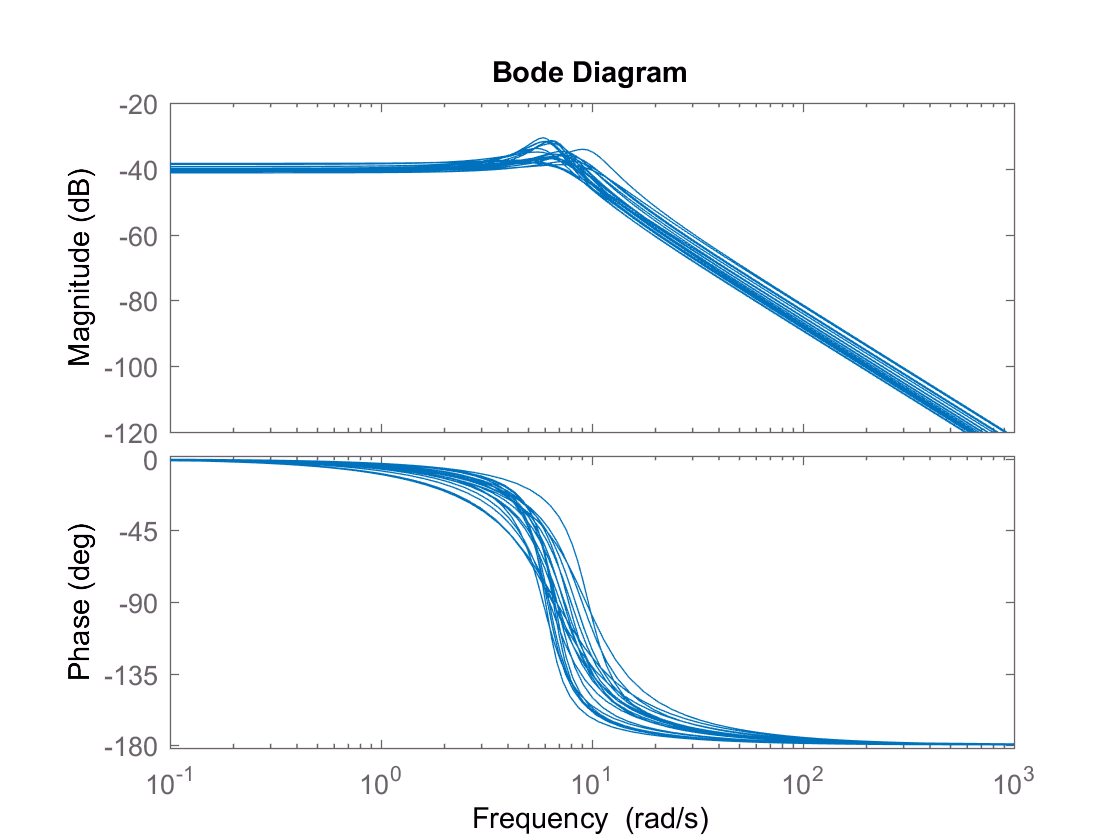

bode(G)

Now we want to find a single multiplicative uncertainty model that deals with all of the variations.  Matlab has a command for that.  First we'll create a large vector potential frequency responses.

Gvec = usample(G,100);  %Create 100 Monte Carlo samples of G
[P,info] = ucover(Gvec,G.NominalValue,4);  %Find the best 4th order multiplicative uncertainty
P

*ucover* is finding the uncertain plant P with 4th order multiplicative uncertainty that best fits the data it receives.  Note that Gvec *could* have come from experimental frequency response data, but here we're just using *ucover* to replace the three parametric uncertainties with a single multiplicative uncertainty.  Let's see how well it did.


P =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 6 states.
  The model uncertainty consists of the following blocks:
    Gvec_InputMultDelta: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences

Type "P.NominalValue" to see the nominal value, "get(P)" to see all properties, and "P.Uncertainty" to interact with the uncertain elements.



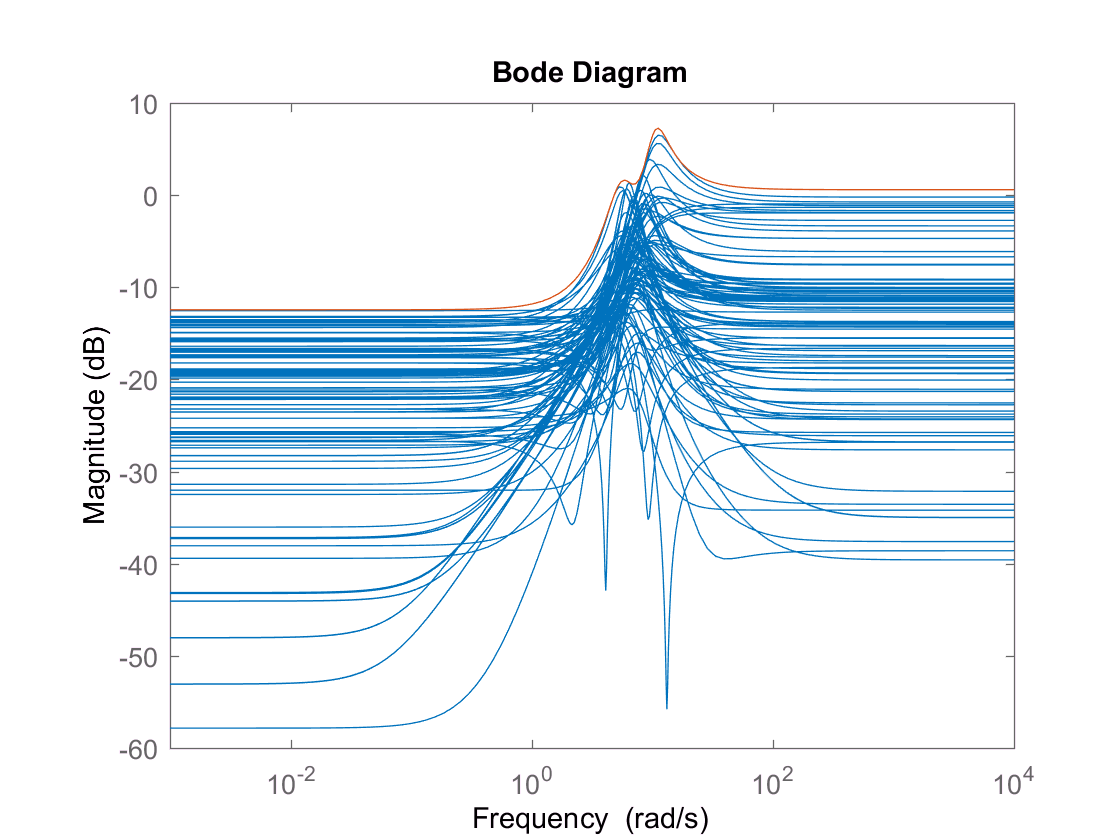

bodemag((Gvec-G.NominalValue)/G.NominalValue,info.W1) %Gvec: 100 samples

To find the weight we look at the info structure that is returned with the uncertain system.  Whether or not the muliplicative weight actually covers the system of course depends on the samples that were used to fit the weight being representative of the behavior.  This caveat is certainly true when collecting experimental responses as well.

Example 2

This example shows a time delay uncertainty.  Consider the plant


$$G_p(s) = \frac{1}{s^2}e^{-Ts}$$


where each parameter is on the interval (2,3).  For simplicity, we usually want to create a nominal model without time delay (need a rational transfer function for synthesis).

[P,info] = ucover(exp(-0.1*s)-1,tf(1,1),1)


P =

  Uncertain continuous-time state-space model with 1 outputs, 1 inputs, 1 states.
  The model uncertainty consists of the following blocks:
    InputMultDelta: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences

Type "P.NominalValue" to see the nominal value, "get(P)" to see all properties, and "P.Uncertainty" to interact with the uncertain elements.



info =          Ord1: 1
         Ord2: 0
        W1opt: [1x1 frd]
        W2opt: [1x1 frd]
           W1: [1x1 ss]
           W2: 1
         Type: 'InputMult'
    DeltaName: 'InputMultDelta'
     Residual: [1x1 frd]


In this case we can do better by hand...

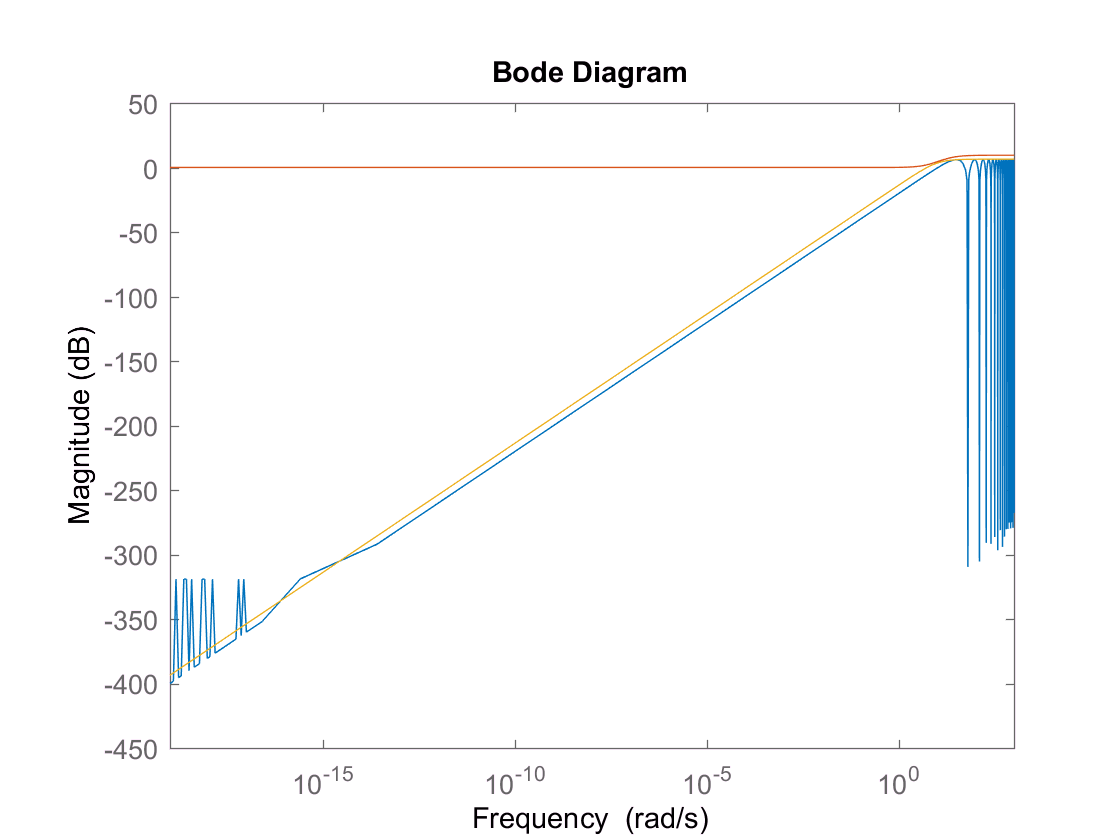

WI = 0.21*s/(0.1*s+1);
Gp= 1/s^2*exp(-0.1*s);
bodemag((Gp-1/s^2)/(1/s^2),info.W1,WI)